# Ejercicio Nº9

clear;clc;

## Valores de los componentes

R1=1;
R2=1;
R3=1;
R4=1;
R5=1;
C1=0.1;
C2=0.1;
C3=0.1;
C4=0.1;
C5=0.1;

## Condiciones iniciales

vc1=0;
vc2=0;
vc3=0;
vc4=0;
vc5=0;
Xant=[vc1;vc2;vc3;vc4;vc5];

## Valores de tiempo y paso

ti=0;
tf=10;
h=0.01;

## Matrices de forma generalizadas

M=[C1 0 0 0 0; 0 C2 0 0 0; 0 0 C3 0 0; 0 0 0 C4 0; 0 0 0 0 C5];
N=[1/R1+1/R2 -1/R2 0 0 0; -1/R2 1/R2+1/R3 -1/R3 0 0; 0 -1/R3 1/R3+1/R4 -1/R4 0; 0 0 -1/R4 1/R4+1/R5 -1/R5; 0 0 0 -1/R5 1/R5];

## Método Backward Euler pulso

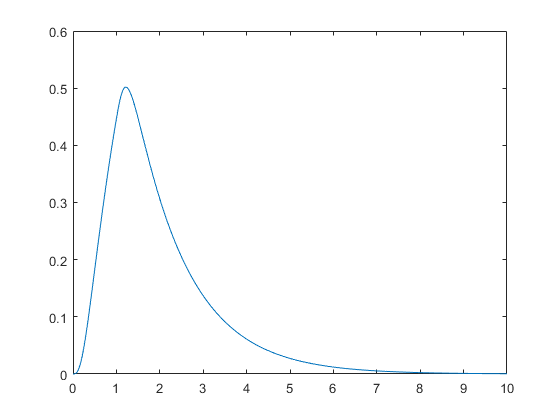

solu=[];
it=1;
for i= ti:h:tf
    %Fuente variable
    if i<1
        E(it,1)=1;
    else
        E(it,1)=0;
    end

    %Se calcula el valor de la matriz u para cada punto 
    u=[E(it,1)/R1;0;0;0;0];
    
    X=((((1/h).*M)+N)\u) + ((((1/h).*M)+N)\((1/h).*M)*Xant);
    
    solu=[solu X];
    Xant=X;
    it=it+1;
end
t=ti:h:tf;
plot(t,solu(5,:))

## Método Backward Euler impulso

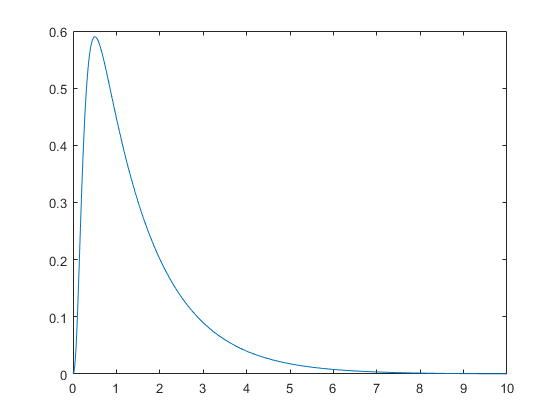

solu=[];
it=1;
for i= ti:h:tf
    %Fuente variable
    if i<2*h
        E(it,1)=50;
    else
        E(it,1)=0;
    end

    %Se calcula el valor de la matriz u para cada punto 
    u=[E(it,1)/R1;0;0;0;0];
    
    X=((((1/h).*M)+N)\u) + ((((1/h).*M)+N)\((1/h).*M)*Xant);
    
    solu=[solu X];
    Xant=X;
    it=it+1;
end
t=ti:h:tf;
plot(t,solu(5,:))